# Deep Learning Aplicado a la Detección Automática de Valvulopatías Usando Sonidos Cardíacos.

John Jairo Gelpud Chachinoy$^1$, Silvia Gabriela Castillo Pastuzan$^2$

Director: PhD. Wilson O. Achicanoy Martínez$^3$

Coasesor: PhD(c). Mario Fernando Jojoa$^4$

$^1$Departamento de Electrónica, Universidad de Nariño, Pasto, e-mail: johnjairog@udenar.edu.co

$^2$Departamento de Electrónica, Universidad de Nariño, Pasto, e-mail:gabrielacast@udenar.edu.co

$^3$Departamento de Electrónica, Universidad de Nariño, Pasto, e-mail:wilachic@udenar.edu.co

$^4$Universidad de Deusto, España, e-mail:mariojojoa@deusto.es

## Introducción

Este código implementa un algoritmo de segmentación automática de sonidos cardíacos y hace parte de los códigos desarrollados como parte del trabajo de tesis de grado para optar por el título de Ingeniero Electrónico de la Universidad de Nariño. El algoritmo de segmentación propuesto se basa en la envolvente de la señal y la función de autocorrelación, y está compuesto de las siguientes etapas: prepocesamiento (decimación, normalización y filtrado),  obtención de la señal envolvente, aplicación de un umbral de energía, creación de ventanas,  estimación del ciclo cardíaco, aplicación de un umbral de distancia, e identificación de los sonidos fundamentales cardíacos (FHS) S1 y S2.

clear all;
close all;
clc;
pause on;

### Inicialización de Variables

main_path = 'D:\UDENAR\Electronic Engineering\Trabajo de Grado';
database = 'Pascal'; %base de datos que se va a utilizar "Physionet" o "Pascal"
dataset = 'Training A Normal'; %dataset que se va a utilizar 
dataset_path = fullfile(main_path, 'Databases', database, dataset); %ruta donde se encuentra el dataset
annotations = table;
labels = table;
if strcmp(database, 'Pascal') %la base de datos Pascal contiene anotaciones manuales de los sonidos cardíacos
    annot_path = fullfile(main_path, 'Databases\Pascal', strcat(dataset, '.csv')); %ruta de las anotaciones manuales de los sonidos
    annotations = readtable(annot_path, 'ReadRowNames', true, 'Delimiter', ',', 'NumHeaderLines', 1); %archivo con las anotaciones manuales
else %la base de datos Physionet incluye las etiquetas de los sonidos cardíacos (-1=normal, 1=anormal) %ruta de las etiquetas de los sonidos
    labels_path = fullfile(main_path, 'Databases\Physionet', dataset, 'REFERENCE.csv'); %archivo con las etiquetas
    labels = readtable(labels_path, 'ReadRowNames', true);
end
version = 'v2.0';
env_method = 'Teager'; %método para obtener la envolvente de la señal "Teager" o "Shannon"

%Definir rutas y archivos para guardar los resultados de la segmentación
%(audios o imágenes segmentadas y las métricas de segmentación).
results_path = fullfile(main_path, 'Results', env_method, version);
metrics_path = fullfile(results_path, 'Segmentation metrics');
seg_hs_path = fullfile(results_path, 'Segmented heart sounds', database);
error_filename = strcat(dataset, ' error.xlsx');
annot_filename = strcat(dataset, ' annotations.xlsx');
metrics_filename = strcat(dataset, ' metrics.xlsx');

global plots;
plots = "on"; %activar ("on") o desactivar ("off") las figuras durante la segmentación

file_type = 'image'; %formato en el que se van a guardar los sonidos segmentados "image" o "audio"
save_hs = false; %"true" para guardar y "false" para no guardar los sonidos segmentados

error_list = []; %lista para almacenar el error de segmentación de cada sonido
metrics_list = []; %lista para almacenar las métricas de cada sonido
s1_metrics_list = []; %lista para guardar las métricas de rendimiento correspondientes al sonido S1
s2_metrics_list = []; %lista para guardar las métricas de rendimiento correspondientes al sonido S2
evaluate = false; %"true" para evaluar los resultados de segmentación

### Cargar Sonidos Cardíacos

Este código carga todos los archivos con formato "wav" que se encuentran en la ruta "dataset_path", y devuelve una celda que contiene los datos de cada sonido, su frecuencia de muestreo y el nombre del archivo.

audios = get_signals(dataset_path);

### Aplicación del Algoritmo de Segmentación a los Sonidos Cardíacos

Para cada sonido en la variable "audios" se aplica el siguiente algoritmo:

for i=10
    try
        %Obtener señal PCG, frecuencia de muestreo y número de muestras.
        audio_idx = i;
        y = audios{audio_idx, 1}; %señal PCG
        fs = audios{audio_idx, 2}; %frecuencia de muestreo
        audio_filename = audios{audio_idx, 3}; %nombre del archivo
        if any(ismember(labels.Properties.RowNames, audio_filename(1:end-4)))
            label = table2array(labels(audio_filename(1:end-4), 1));
            label = max(label, 0);
        else
            label = int2str(-1);
        end
        N = length(y); %número de muestras
        
        %Transformada rápida de Fourier de la señal.
        f = (0:N/2)*fs/N; %vector de frecuencias
        Y = abs(fft(y)); Y = Y(1:floor(N/2)+1); %representación de la señal en el dominio de la frecuencia
        
        figure('Visible', plots);
        subplot(211); plot(y); title('Señal PCG'); xlabel('Muestras'); axis tight;
        subplot(212); plot(f, Y); title('Transformada de Fourier de la señal PCG'); xlabel('f [Hz]'); axis tight;

###             Decimación

La tasa de muestreo de la señal se reduce por un factor de decimación ***D***. El factor de decimación debe asegurar una tasa mínima de muestreo de 2kHz.

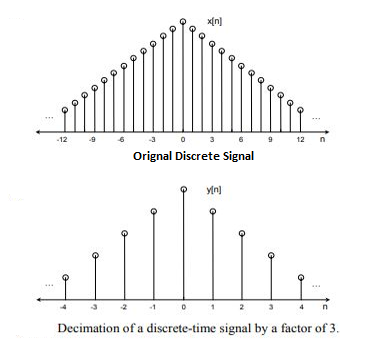

Fig. 1. Decimación de una señal discreta. Disponible en [Down-sampling in MATLAB - GeeksforGeeks](https://www.geeksforgeeks.org/down-sampling-in-matlab/).

        D = floor(fs/2000); %factor de decimación
        fs1 = fs/D; %frecuencia de muestreo de la señal decimada
        yd = decimate(y, D, 'fir'); %señal PCG decimada
        Nd = length(yd); %número de muestras de la nueva señal
        
        %Transformada rápida de Fourier de la señal decimada.
        f1 = (0:Nd/2)*fs1/Nd; %vector de frecuencias
        Yd = abs(fft(yd)); Yd = Yd(1:floor(Nd/2)+1); %representación de la señal en el dominio de la frecuencia
        
        figure("Visible", plots);
        subplot(211); plot(yd); title('Señal PCG decimada'); xlabel('Muestras'); axis tight;
        subplot(212); plot(f1, Yd); title('Transformada de Fourier de la señal decimada'); xlabel('f [Hz]'); axis tight;

###             Normalización

La señal es normalizada en magnitud dividiéndola por su máximo valor absoluto.

        y1 = yd/max(abs(yd)); %señal PCG normalizada
        Y1 = Yd/max(abs(Yd)); %transformada de Fourier normalizada

###             Filtro Adaptativo

Para atenuar el ruido la señal es filtrada utilizando la Transformada Discreta de Wavelet (DWT). Mediante la función "adaptative_filter" se realiza un análisis wavelet a 5 niveles usando la wavelet Coif-5. Así, la señal se descompone en coeficientes de aproximación y coeficientes de detalle para aplicar un umbral adaptativo, mediante una función de umbralización no lineal, a los coeficientes de detalle D4 y D5. Por último, los coeficientes restantes se hacen cero y se reconstruye la señal.

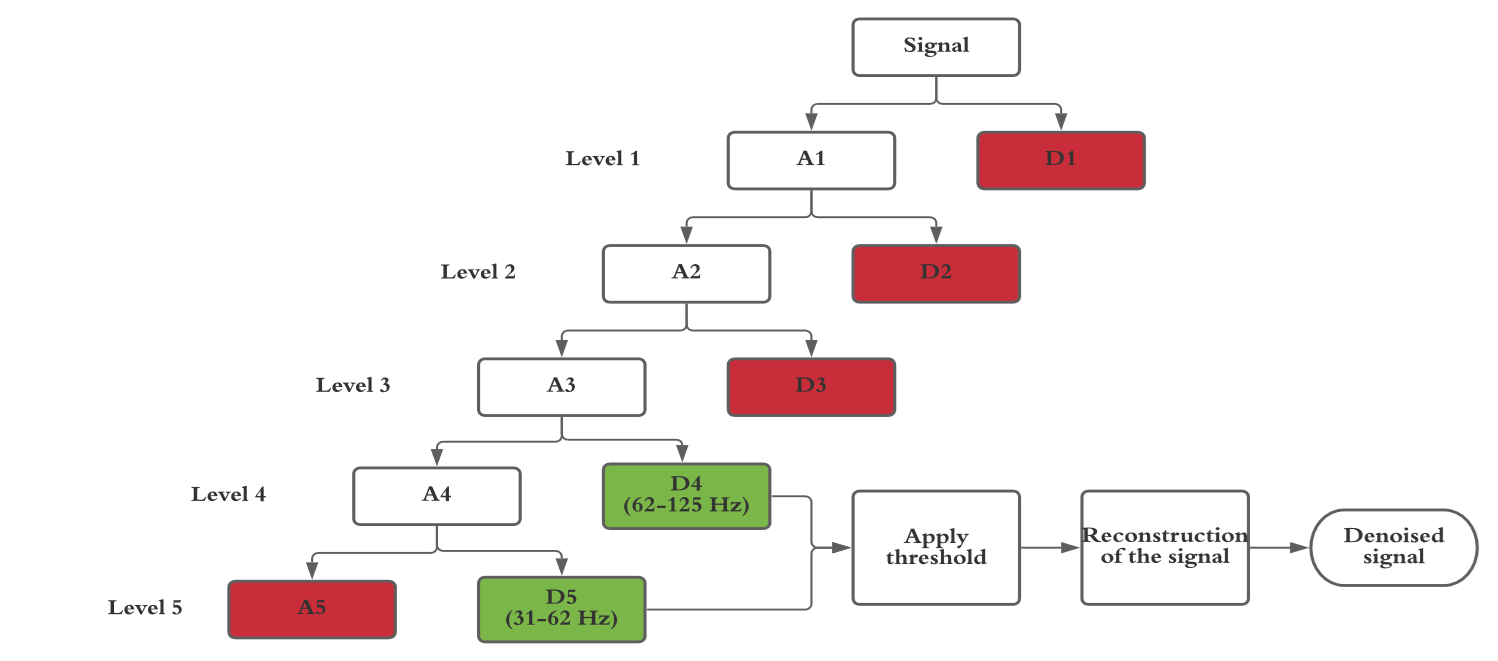

Fig. 2. Filtro adaptativo basado en la DWT. Fuente: Elaboración propia.

        y2 = adaptative_filter(y1, 'coif5'); %señal filtrada
        y2 = y2(1:Nd)/max(abs(y2(1:Nd))); %señal filtrada y normalizada en amplitud
        Y2 = abs(fft(y2)); Y2 = Y2(1:floor(Nd/2)+1); %representación de la señal filtrada en el dominio de la frecuencia

###             Envolvente de la señal

Para calcular la envolvente de la señal filtrada, que es una de las etapas principales de la segmentación, se utiliza el operador de energía de Teager, definido como


$$\textrm{TEO}=x^2 \left\lbrack n\right\rbrack -x\left\lbrack n-1\right\rbrack x\left\lbrack n+1\right\rbrack \;\;\;\;\left(1\right)$$


donde $x\left\lbrack n\right\rbrack$ es la señal PCG filtrada.

Para suavizar la señal envolvente se aplica un promedio móvil y se calcula la raíz cuadrada para reducir la diferencia entre los componentes de gran amplitud y de pequeña amplitud. Después, la señal se normaliza restandole el valor promedio y dividiéndola por la desviación estándar. Por último, todos los valores negativos se hacen cero y se calcula nuevamente la raíz cuadrada. La función "get_envelope" toma la señal filtrada y el número de muestras usado para calcular el promedio móvil, y devuelve la envolvente de la señal.

        env = get_envelope(y2, env_method, 20); %envolvente de la señal PCG preprocesada

###             Umbral de Energía

Con el fin de detectar los límites de cada componente en la señal envolvente se implementa la función "get_on_off_sets" que devuelve las posiciones donde empieza y termina cada componente. Luego, con ayuda de la función "energy_threshold" se calcula la energía de cada componente y se eliminan aquellos cuya energía es menor al promedio de todos los valores de energía. Esta función devuelve una señal cuadrada con los valores de energía de los componentes que pasaron el umbral, así como la señal envolvente umbralizada.

        [onsets, offsets, env] = get_on_off_sets(env);
        [env_energy, th_env_energy, th_env, energy_th] = energy_threshold(env, onsets, offsets, 1);

###             Ventanas

La señal obtenida después de aplicar el umbral de energía se divide en ventanas cuya duración es de al menos 2 segundos. La función "get_windows" devuelve una matriz de $n_w \times n_s$, donde $n_{w\;}$ es el número de ventanas resultantes y $n_s$ es el número de muestras en cada ventana.

        n_windows = floor((Nd/fs1)/2); %número de ventanas
        n_windows(n_windows==0) = 1; %la señal no se divide si su duración es menor que 2 segundos
        n_samples = floor(Nd/n_windows); %número de muestras en cada ventana
        env_w = get_windows(th_env, n_windows, n_samples); %matriz que contiene los segmentos de la señal PCG

###             Estimación del Ciclo Cardíaco

Para estimar la periodicidad de la señal se utiliza la función parcial de autocorrelación, dada por


$$r\left\lbrack n\right\rbrack =\frac{1}{N}\sum_{m=0}^{N-n-1} x\left\lbrack m\right\rbrack x\left\lbrack m+n\right\rbrack \;\;\;\;\left(2\right)$$


donde $n=0,1,\ldotp \ldotp \ldotp ,N-1,N,$ y $N$ es el número de muestras de la señal $x$.

La función de autocorrelación se aplica a cada ventana con el fin de estimar la duración del ciclo cardíaco y la distancia mínima entre los sonidos cardíacos fundamentales (FHS) S1 y S2. La función "per_estimation" calcula la autocorrelación, y estima el ciclo cardíaco y la distancia mínima entre los FHS de cada ventana. El ciclo cardíaco está definido como la distancia, en muestras, entre los dos picos de mayor amplitud de la función de autocorrelación. Por otro lado, para estimar la distancia mínima entre los FHS se debe encontrar el pico de mayor amplitud en medio de los dos picos más altos que se utilizaron para estimar el ciclo cardíaco, la mínima distancia entre el tercer pico encontrado y los otros dos picos será la distancia mínima entre los FHS.

        [env_corr, cc_samples, cc_std, min_lengths] = per_estimation(env_w, 2, 600, 2600, n_windows, n_samples, 'median');
        cc_sec = cc_samples/fs1; %ciclo cardíaco en segundos

###             Umbral de Distancia

Después de estimar la periodicidad de la señal PCG, se identifican aquellos componentes cuya separación es menor que la mínima distancia entre los FHS. Los componentes de menor energía son eliminados, pues se consideran falsos componentes que pasaron el umbral de energía. La función "distance_threshold" calcula la distancia entre los componentes adyacentes de la señal empezando desde la muestra cero para luego identificar aquellos que se encuentran demasiado cerca. Posteriormente, se calcula la energía de cada par de componentes y se elimina aquel que posee menor energía, este proceso se repite hasta que se hayan eliminado todos los componentes con separación menor a la distancia mínima entre los FHS.

        uncertainty = 0;
        if sum(min_lengths==0)>=round(n_windows*0.75)
            mean_min_lengths = 300;
            uncertainty = 1;
        else
            mean_min_lengths = max(mean(min_lengths(min_lengths~=0)), 300);
        end
        [th_env, th_env_energy] = distance_threshold(th_env, th_env_energy, mean_min_lengths, 0.25);
        [onsets, offsets] = get_on_off_sets(th_env);
        non_period =  mean(offsets-onsets)*2>0.25*cc_samples&&uncertainty;

###             Identificación de Componentes del Sonido Cardíaco

La etapa final del método de segmentación propuesto consiste en identificar los componentes S1 y S2. Los FHS son localizados con ayuda de una señal cuadrada con periodo igual al ciclo cardíaco estimado. Esta señal se alinea temporalmente con la envolvente de la señal PCG identificando el punto máximo de la correlación cruzada entre las dos señales. 

Después de alinear ambas señales se identifican los componentes que corresponden a un tipo de sonido fundamental cardíaco, estos son los picos de la envolvente más cercanos a los componentes de la señal cuadrada alineada. Los picos identificados se descartan y se repite el proceso para encontrar los componentes que corresponden al FHS restante.

Para identificar a qué tipo de FHS corresponden los componentes identificados se tienen en cuenta la distancia mínima entre los sonidos S1 y S2 estimada y que, en general, el intervalo sistólico (S1S2) es más corto que el intervalo diastólico (S2S1).

        if ~non_period
            disp(strcat(audio_filename, ' method 1'))
            [s1_onsets, s2_onsets] = get_hs_method_1(y2, th_env, cc_samples, mean_min_lengths, D, 0.25, env_method);
        else
            disp(strcat(audio_filename, ' method 2'))
            [s1_onsets, s2_onsets] = get_hs_method_2(th_env, cc_samples, D);
        end

###             Visualización de Resultados

        if any(ismember(annotations.Properties.RowNames, audio_filename(1:end-4))) %existen anotaciones manuales de la señal PCG
            gt_s1 = table2array(annotations(audio_filename(1:end-4), 1:2:end)); %anotaciones manuales de los sonidos S1
            gt_s2 = table2array(annotations(audio_filename(1:end-4), 2:2:end)); %anotaciones manuales de los soniods S2
            
            figure('Visible', plots);
            subplot(211);
            plot(y/max(abs(y))); grid on; hold on; xlabel('Muestras'); ylabel('Amplitud'); title('Automatic segmentation');
            stem(s1_onsets, ones(length(s1_onsets), 1), 'g', 'filled');
            stem(s2_onsets, ones(length(s2_onsets), 1), 'r', 'filled'); axis tight;
            subplot(212);
            plot(y/max(abs(y))); grid on; hold on; xlabel('Muestras'); ylabel('Amplitud'); title('Manual segmentation');
            stem(gt_s1, ones(length(gt_s1), 1), 'g', 'filled');
            stem(gt_s2, ones(length(gt_s2), 1), 'r', 'filled'); axis tight;
        else %no existen anotaciones manuales de la señal PCG
            figure('Visible', plots);
            plot(y/max(abs(y))); grid on; hold on; xlabel('Muestras'); ylabel('Amplitud'); title('Automatic segmentation');
            stem(s1_onsets, ones(length(s1_onsets), 1), 'g', 'filled');
            stem(s2_onsets, ones(length(s2_onsets), 1), 'r', 'filled'); axis tight;
        end

###             Segmentación de la Señal PCG

Luego de identificar los sonidos S1 y S2 la señal es dividida en ciclos cardíacos compuestos por el primer sonido cardíaco (S1), la sístole, el segundo sonido cardíaco (S2) y la diástole. La función "split" utiliza los límites de los sonidos S1 identificados para dividir la señal PCG original.

        if save_hs
            yw = split(y, s1_onsets, D, cc_samples, seg_hs_path, audio_filename, fs, label, file_type);
        end

###             Evaluación del Algoritmo de Segmentación

Finalmente, se evalúan los resultados de la segmentación automática, para lo cual se calculan diferentes medidas de rendimiento, incluyendo el error promedio, la sensitividad (Se), el valor predictivo positivo (P), la exactitud (Acc) y el F1-score.

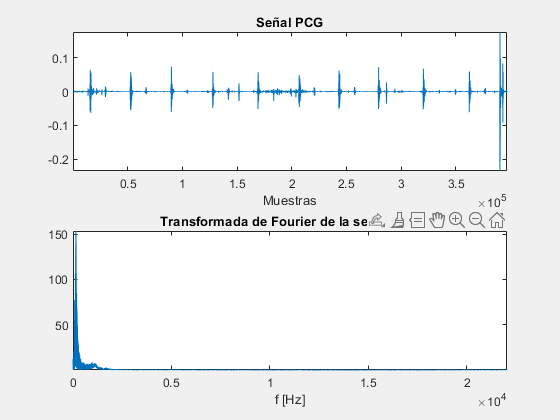

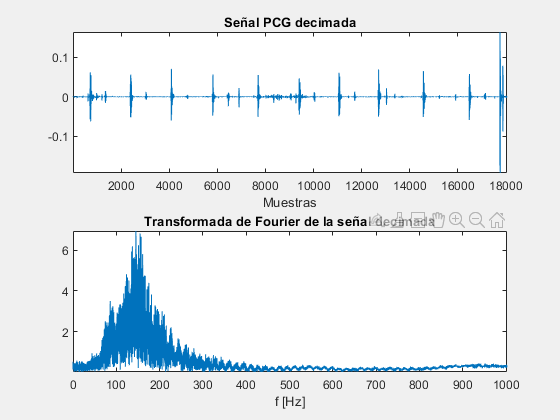

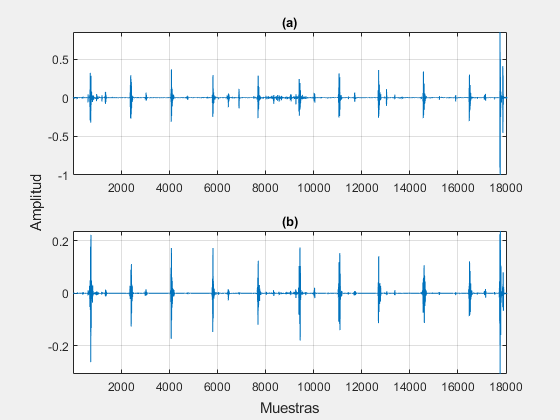

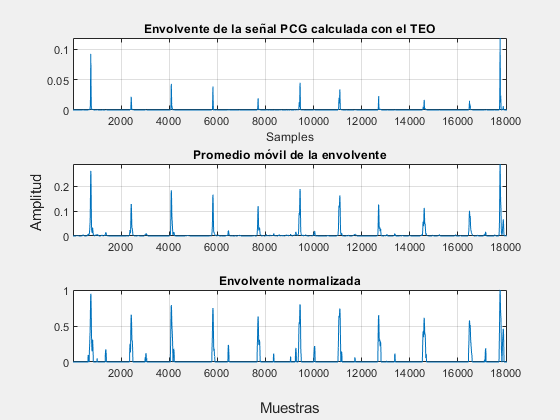

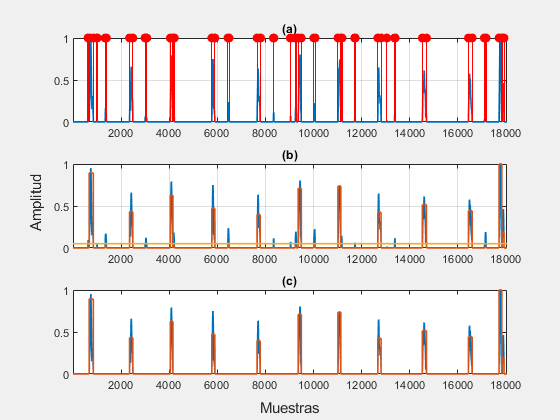

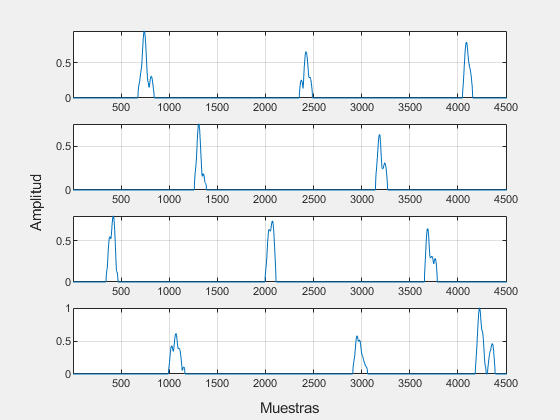

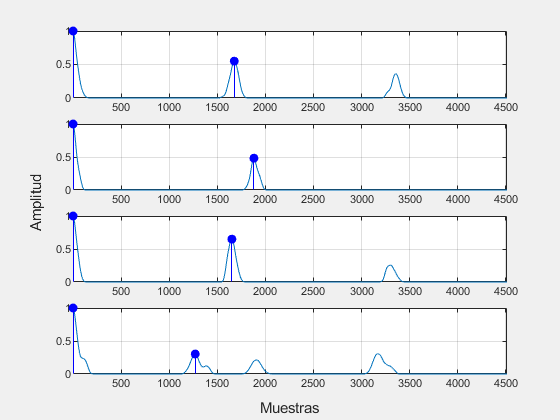

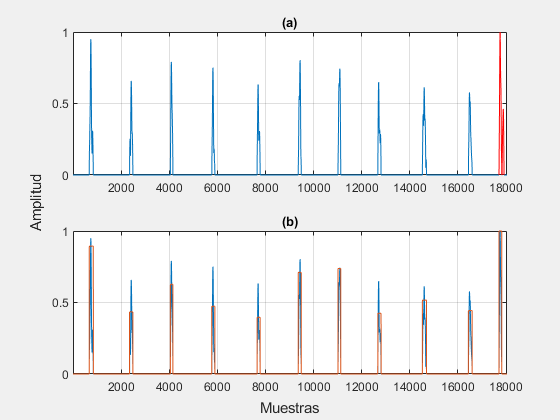

201103140132.wav method 1


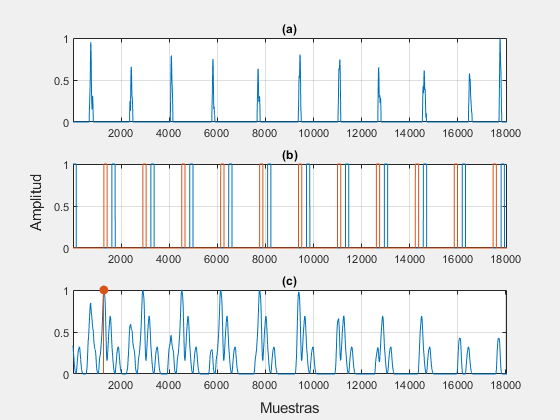

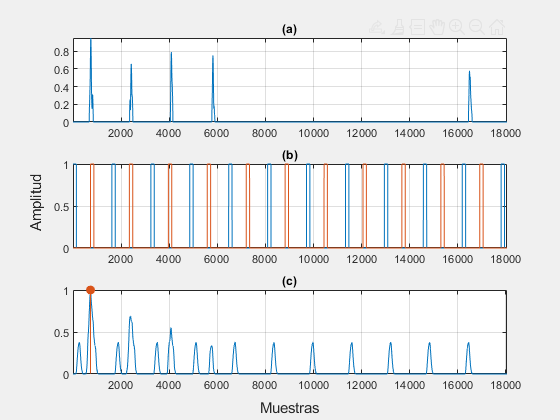

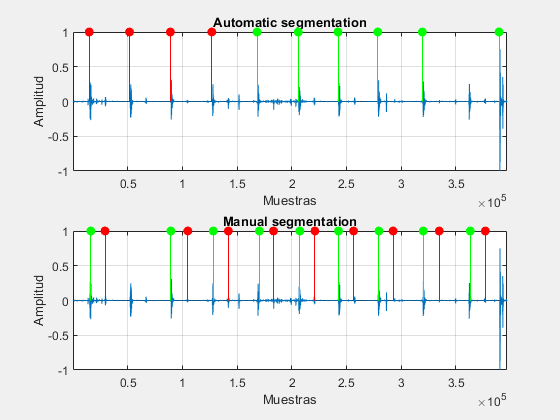

        if evaluate
            [error, metrics, s1_metrics, s2_metrics] = get_results(annot_path, audio_filename, i, s1_onsets, s2_onsets, fs, metrics_path, error_filename, annot_filename, metrics_filename);
            error_list = [error_list; error]; %vector que almacena los errores promedio de todas las grabaciones
            s1_metrics_list = [s1_metrics_list; s1_metrics']; %vector que almacena los valores TP, TN y FN para los sonidos S1 de todas las grabaciones
            s2_metrics_list = [s2_metrics_list; s2_metrics']; %vector que almacena los valores TP, TN y FN para los sonidos S2 de todas las grabaciones
            metrics_list = [metrics_list; metrics']; %vector que almacena los valores TP, TN y FN para los sonidos S1 y S2 de todas las grabaciones
        end
    catch ME %ocurrió un error durante la segmentación
        disp(strcat('Error while segmenting audio ', num2str(i), ':', audio_filename));
        disp(ME);
        disp(ME.stack);
    end
end

## Resultados de Segmentación

Después de aplicar el algoritmo de segmentación a todos los sonidos se calcula el error promedio y las medidas de rendimiento para todo el conjunto de datos.

if ~(isempty(error_list)) %el vector que almacena los errores promedio de cada sonido no está vacío
    total_error = sum(error_list) %error total de todo el conjunto de datos
    
    s1_total = sum(s1_metrics_list, 1); %número de TP, TN, y FN para los sonidos S1 en todo el conjunto de datos
    s1_tp = s1_total(1); %número de anotaciones correctas (TP) para los sonidos S1 en todo el conjunto de datos
    s1_fn = s1_total(2); %número de componentes S1 no identificados (FN) en todo el conjunto de datos
    s1_fp = s1_total(3); %número de componentes S1 adicionales
    s1_Se = s1_tp/(s1_tp+s1_fn); %sensibilidad total obtenida para los sonidos S1
    s1_P = s1_tp/(s1_tp+s1_fp); %valor predictivo positivo total obtenido para los sonidos S1
    s1_Acc = s1_tp/(s1_tp+s1_fn+s1_fp); %exactitud de los sonidos S1 en todo el conjunto de datos
    s1_F1 = 2*s1_Se*s1_P/(s1_Se+s1_P); %F1-score para los sonidos S1 en todo el conjunto de datos
    
    s2_total = sum(s2_metrics_list, 1); %número de TP, TN, y FN para los sonidos S2 en todo el conjunto de datos
    s2_tp = s2_total(1); %número de anotaciones correctas para los sonidos S2 en todo el conjunto de datos
    s2_fn = s2_total(2); %número de componentes S2 no identificados en todo el conjunto de datos
    s2_fp = s2_total(3); %número de componentes S2 adicionales 
    s2_Se = s2_tp/(s2_tp+s2_fn); %sensibilidad total obtenida para los sonidos S2
    s2_P = s2_tp/(s2_tp+s2_fp); %valor predictivo positivo total obtenido para los sonidos S2
    s2_Acc = s2_tp/(s2_tp+s2_fn+s2_fp); %exactitud de los sonidos S2 en todo el conjunto de datos
    s2_F1 = 2*s2_Se*s2_P/(s2_Se+s2_P); %F1-score para los sonidos S2 en todo el conjunto de datos
    
    total_metrics = sum(metrics_list, 1); %número de TP, TN, y FN para los sonidos S1 y S2 en todo el conjunto de datos
    tp = total_metrics(1); %número de anotaciones correctas en todo el conjunto de datos
    fn = total_metrics(2); %número de componentes no identificados en todo el conjunto de datos
    fp = total_metrics(3); %número de componentes adicionales 
    Se = tp/(tp+fn); %sensibilidad total obtenida para los sonidos S1 y S2
    P = tp/(tp+fp); %valor predictivo positivo total obtenido para los sonidos S1 y S2
    Acc = tp/(tp+fn+fp); %exactitud de los sonidos S1 y S2 en todo el conjunto de datos
    F1 = 2*Se*P/(Se+P); %F1-score para los sonidos S1 y S2 en todo el conjunto de datos
    
    writecell({'Total', total_error}, fullfile(metrics_path, error_filename), 'WriteMode', 'append'); %el error total se guarda en un archivo .xlsx
    writecell({'Total S1', [s1_tp; s1_fn; s1_fp; s1_Se; s1_P; s1_Acc; s1_F1]}, fullfile(metrics_path, metrics_filename), ...
        'WriteMode', "append"); %las métricas de rendimiento para los sonidos S1 en todo el conjunto de datos se guardan en un archivo .xlsx
    writecell({'Total S2', [s2_tp; s2_fn; s2_fp; s2_Se; s2_P; s2_Acc; s2_F1]}, fullfile(metrics_path, metrics_filename), ...
        'WriteMode', "append"); %las métricas de rendimiento para los sonidos S2 en todo el conjunto de datos se guardan en un archivo .xlsx
    writecell({'Total S1/S2', [tp; fn; fp; Se; P; Acc; F1]}, fullfile(metrics_path, metrics_filename), 'WriteMode', 'append'); %las medidas de rendimiento
    %para los sonidos S1 y S2 se guardan en un archivo .xlsx
end

## Referencias

- Jain, P.K., Tiwari, A.K.: An adaptive thresholding method for the wavelet based denoising of phonocardiogram signal. Biomed. Signal Process. Control 38, 388–399 (2017).  [https://doi.org/10.1016/j.bspc.2017.07.002](https://doi.org/10.1016/j.bspc.2017.07.002)

- Sabir, M.K.: PCG signal analysis using Teager energy operator & autocorrelation function. In: International Conference on Computer Medical Applications, ICCMA 2013 (2013).  [https://doi.org/10.1109/ICCMA.2013.6506176](https://doi.org/10.1109/ICCMA.2013.6506176)

- Liu, Q., Wu, X., Ma, X.: An automatic segmentation method for heart sounds. BioMedical Eng. OnLine 17(1), 106 (2018).  [https://doi.org/10.1186/s12938-018-0538-9](https://doi.org/10.1186/s12938-018-0538-9)

- M. A. Alonso-Arévalo, A. Cruz-Gutiérrez, R. F. Ibarra-Hernández, E. García-Canseco, and R. Conte-Galván, “Robust heart sound segmentation based on spectral change detection and genetic algorithms,” *Biomed. Signal Process. Control*, vol. 63, no. October 2019, 2021, doi:10.1016/j.bspc.2020.102208.

- Bentley, P., Nordehn, G., Coimbra, M., Mannor, S.: The PASCAL Classifying Heart Sounds Challenge 2011 (CHSC2011) Results (2011).[http://www.peterjbentley.com/heartchallenge/index.html](http://www.peterjbentley.com/heartchallenge/index.html)

- Liu, C., et al.: An open access database for the evaluation of heart sound algorithms. Physiol. Meas. 37(12), 2181–2213 (2016).  [https://doi.org/10.1088/0967-3334/37/12/2181](https://doi.org/10.1088/0967-3334/37/12/2181)

- Gelpud J., Castillo S., Jojoa M., Garcia-Zapirain B., Achicanoy W., Rodrigo D. (2021) Deep Learning for Heart Sounds Classification Using Scalograms and Automatic Segmentation of PCG Signals. In: Rojas I., Joya G., Català A. (eds) Advances in Computational Intelligence. IWANN 2021. Lecture Notes in Computer Science, vol 12861. Springer, Cham. [https://doi.org/10.1007/978-3-030-85030-2_48](https://doi.org/10.1007/978-3-030-85030-2_48)